close all; clear; clc

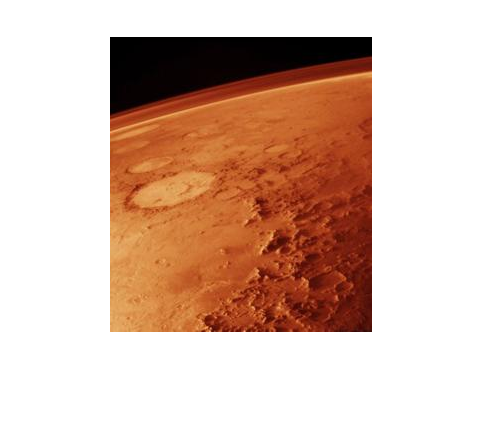

% original image
img = imread('.\Mars.JPG');
imshow(uint8(img))

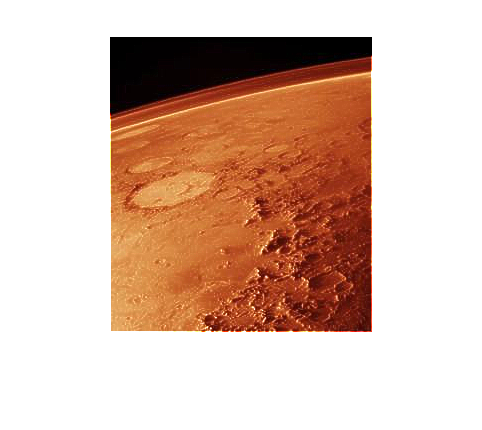

% sharpen image by mean subtraction
% s=3, w=3
sharpened_1 = sharpen_1(img, 3, 3);
imshow(uint8(sharpened_1))

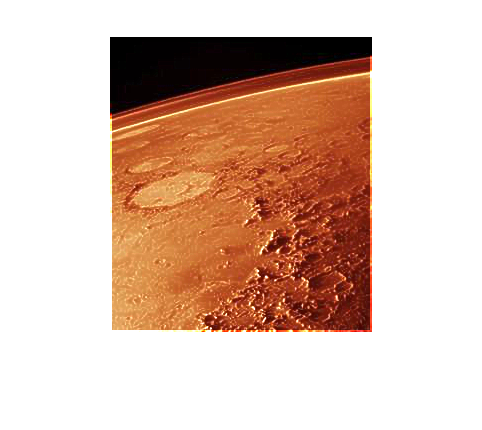

% s=5, w=3
sharpened_2 = sharpen_1(img, 5, 3);
imshow(uint8(sharpened_2))

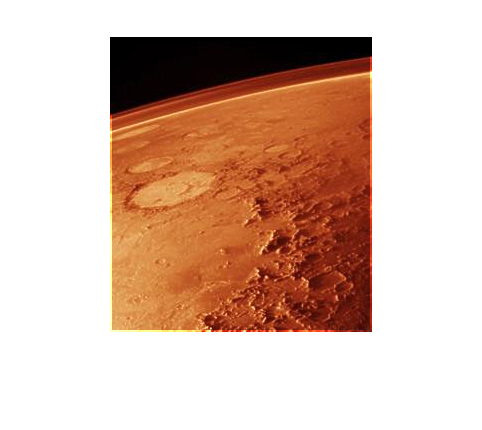

% s=5, w=1
sharpened_3 = sharpen_1(img, 5, 1);
imshow(uint8(sharpened_3))

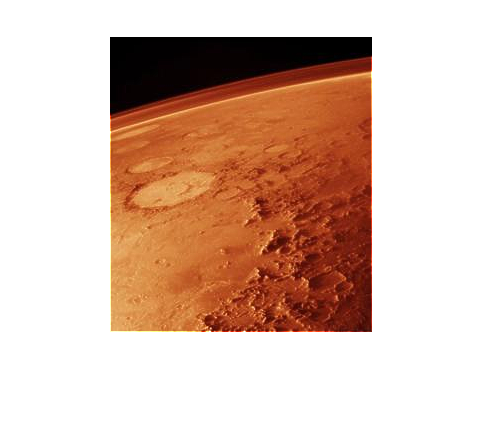

% s=3, w=1
sharpened_4 = sharpen_1(img, 3, 1);
imshow(uint8(sharpened_4))

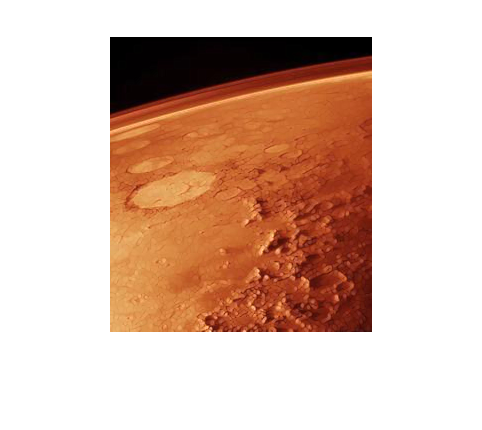

% sharpen image by sobel edge detection
[x, y, z] = size(img);
S = ones(x, y, z);
% w = 300
S(:,:,1) = sharpen_2(img(:,:,1), 300);
S(:,:,2) = sharpen_2(img(:,:,2), 300);
S(:,:,3) = sharpen_2(img(:,:,3), 300);
imshow(uint8(S))

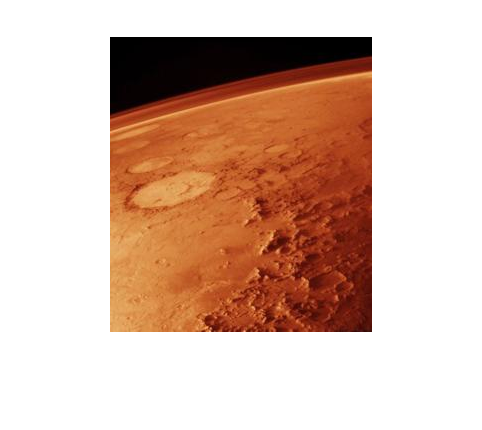

% w = 50
S2 = ones(x, y, z);
S2(:,:,1) = sharpen_2(img(:,:,1), 50);
S2(:,:,2) = sharpen_2(img(:,:,2), 50);
S2(:,:,3) = sharpen_2(img(:,:,3), 50);
imshow(uint8(S2))

- The one in part 1 (sharpening using mean subtraction) produces the better output.

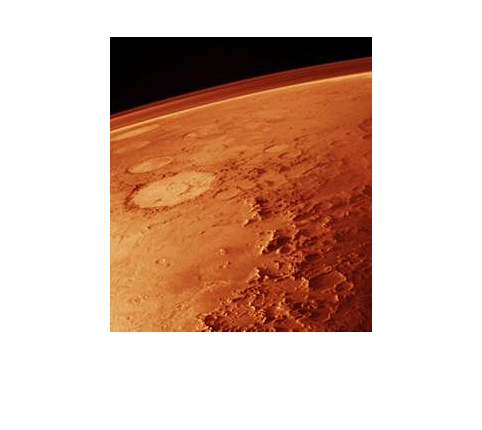

% sharpen using the built-in function
imshow(imsharpen(img))

Also, see the example "**Sharpen an Image Using the GPU**" in this link: https://www.mathworks.com/help/distcomp/run-matlab-functions-on-a-gpu.html

# External Functions

function sharpened = sharpen_1(img, kernel_size, factor)

inc = floor(kernel_size/2);

[x, y, z] = size(img);
averaged = ones(x, y, z);
edges = ones(x, y, z);

bound_1 = floor(1 + inc);
bound_2 = floor(x - inc);
bound_3 = floor(y - inc);
for c = 1:z
    for i = bound_1:bound_2
        for j = bound_1:bound_3
            kernel = img(i-inc:i+inc, j-inc:j+inc, c);
            averaged(i, j, c) = mean(kernel(:));
        end
    end
end

edges = uint8(img) - uint8(averaged);
sharpened = img + edges*factor;

end

function sharpened = sharpen_2(img, factor)

[~,~,gv,gh] = edge(img,'sobel'); % documentation: help edge - [BW,thresh,gv,gh] = edge(I,..)
[x, y, z] = size(img);
M_edges = zeros(x,y,z);

M_edges = sqrt(gv.^2 + gh.^2);
sharpened = double(img) + M_edges*factor;

end
